# **Visualisation and map manipulation in Cell Designer (PART 1) **

## Authors: 

## Jennifer Modamio, Anna Danielsdottir, Systems Biochemistry group, University of Luxembourg.

## Nicolas Sompairac, Bioinformatics and Computational Systems Biology of Cancer, Institut Curie.

## **Reviewer(s): Ronan Fleming, Inna Kuperstein and Andrei Zinovyev. **

## INTRODUCTION

Visualisation of data on top of biochemical pathways is an important tool for interpreting the results of constrained-based modeling. It can be an invaluable aid for developing an understanding of the biological meaning implied by a prediction. Biochemical network maps permit the visual integration of model predictions with the underlying biochemical context. Patterns that are very difficult to appreciate in a vector can often be much better appreciated by studying a generic map contextualised with model predictions. Genome-scale biochemical network visualisation is particularly demanding. No currently available software satisfies all of the requirements that might be desired for visualisation of predictions from genome-scale models.

Here we present a tool for the visualisation of computational predictions from The Constraint-based Reconstruction and Analysis Toolbox (COBRA Toolbox) [1] to available metabolic maps developed in CellDesigner [2].

Several maps are used in this tutorial for illustration: (i) a comprehensive mitochondrial metabolic map compassing 1263 metabolic reactions extracted from the latest version of the human cellular metabolism, Recon 3D [3]. (ii) Small map contaning Glycolisis and TCA for faster testing and manipulation. (iii) A mitochondria map combining metabolic pathways with protein-protein interactions (PPI). Proteins and complexes implicated in mitochondrial reactions have been extracted from the Parkinson Disease map (PDMap) [4].

In this tutorial, manipulation of CellDesgner maps in COBRA toolbox and visualising model predictions is explained. The main covered topics are:

- Loading metabolic models and models containing both metabolic and regulatory networks constructed in CellDesigner 

- Detection and correction of discrepancies between map and models

- Basic map manipulation (change color and size of nodes and reactions, directionality of reactions, reaction types...) 

- Basic model analysis visualisation (visualisation of Flux Balance Analysis) 

## EQUIPMENT SETUP 

To visualise the metabolic maps it is necessary to obtain the version 4.4 of CellDesigner. This software can be freely downloaded from: 

[http://www.celldesigner.org/download.html](http://www.celldesigner.org/download.html)

## Initialise The Cobra Toolbox and set the solver. 

If needed, initialise the cobra toolbox.

initCobraToolbox(false) %don't update the toolbox

The present tutorial can run with glpk package, which does not require additional installation and configuration. Although, for the analysis of large models it is recommended to use the GUROBI package.

if changeCobraSolver('gurobi', 'LP', 0)
    changeCobraSolver('gurobi6','all')
end

## Model setup. 

In this tutorial, we provided two exclusive metabolic models. A mitochondrial model and a small metabolic model specific for Glycolysis and Citric acid cycle. Both models were extracted from the latest version of the database of the human cellular metabolism, Recon 3D [3]. For extra information about metabolites structures and reactions, and to download the latest COBRA model releases, visit the Virtual Metabolic Human database (VMH, [https://vmh.life).](https://vmh.life).) 

Before proceeding with the simulations, load the model into the workspace: 

if 1
    modelFileName = 'Recon2.0model.mat';
else
    modelFileName = 'Recon3DModel_301.mat';
end
modelDirectory = getDistributedModelFolder(modelFileName);
modelFileName = [modelDirectory filesep modelFileName];
if 0
    model = readCbModel(modelFileName);
else
    load([modelDirectory filesep modelFileName])
end

## PROCEDURE

Aforementioned, two kind of maps will be used along the tutorial. Depending on the nature of the species in the map (metabolites or proteins), different functions will be used to import the XML file produced in CellDesigner into MATLAB.

## 1. Import a CellDesigner XML file to MATLAB environment

## A) Parse a Metabolic map

The `transformXML2Map` function parses an XML file from Cell Designer (CD) into a Matlab structure. This structure is organised similarly to the structure found in the COnstraint-Base and Reconstruction Analysis (COBRA) models.

Load two types of metabolic maps: 

- A small metabolic model representative of glycolysis and citric acid cycle. 

- A bigger metabolic map representative of the mitochondrial metabolism. 

[xmlGly, mapGly] = transformXML2Map('glycolysisAndTCA.xml');
[xmlMitoMetab, mapMitoMetab] = ...
    transformXML2Map('metabolicMitochondria.xml');

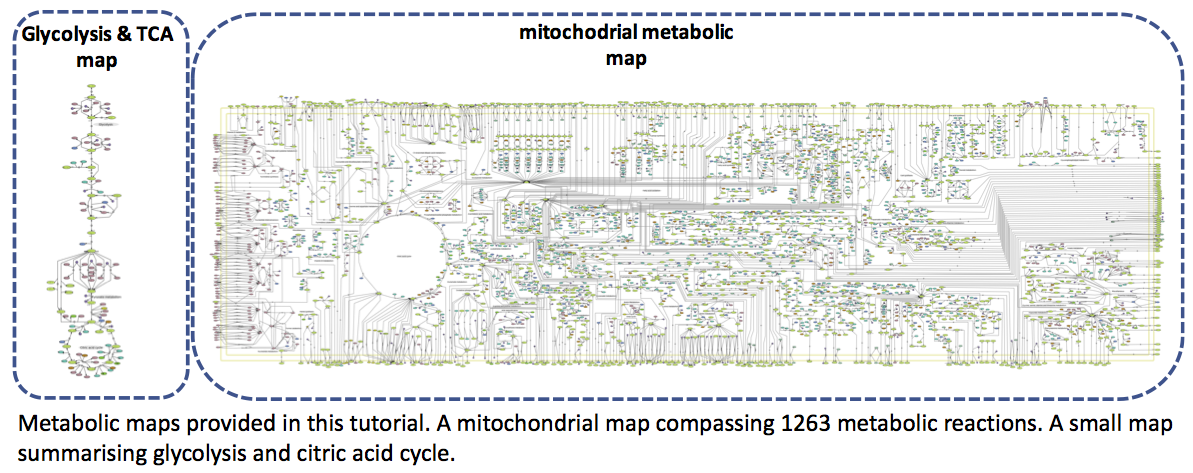

This function internally calls the function `xml2struct` which parses the XML file to a general Matlab structure. Afterwards, this general structure is reorganised. Due to this internal function, there are two outputs: "`xml`" is the general Matlab structure obtain from `xml2struct` function, whereas "`map`" is the desired final structure that could be later manipulated.

## B) Parse a Metabolic map combined with Protein-Protein-Interactions (PPI)

The `transformFullXML2Map` function parses an XML file from Cell Designer (CD) into a Matlab structure. The resultant structure contains all the information commonly stored in a metabolic map, plus extra information corresponding to proteins and complexes.

[xmlPPI, mapPPI] = transformFullXML2Map('metabolicPPIMitochondria.xml');

***NOTE! ****The XML file to be parsed must be in the current folder in MATLAB when executing the function.*

**TIMING**

The time to parse a Cell Designer map from a XML file to a MATLAB structure or vice-versa depends on the size of the map, and can vary from seconds to minutes.

## TROUBLESHOOTING (Control error check)

In order to properly visualise the modeling obtained during model analysis, the map used for the visualisation must match with the model under study. Errors in reaction or metabolite names are highly common, leading to mismatches and therefore wrong representation of data.

In order to ensure a proper visualisation of the outputs coming from model analysis, a control error check is highly recommended.

The function `checkCDerrors` gives four outputs summarising all possible discrepancies between model and map.

[diffReactions, diffMetabolites, diffReversibility, diffFormula] = ...
    checkCDerrors(mapGly, model);

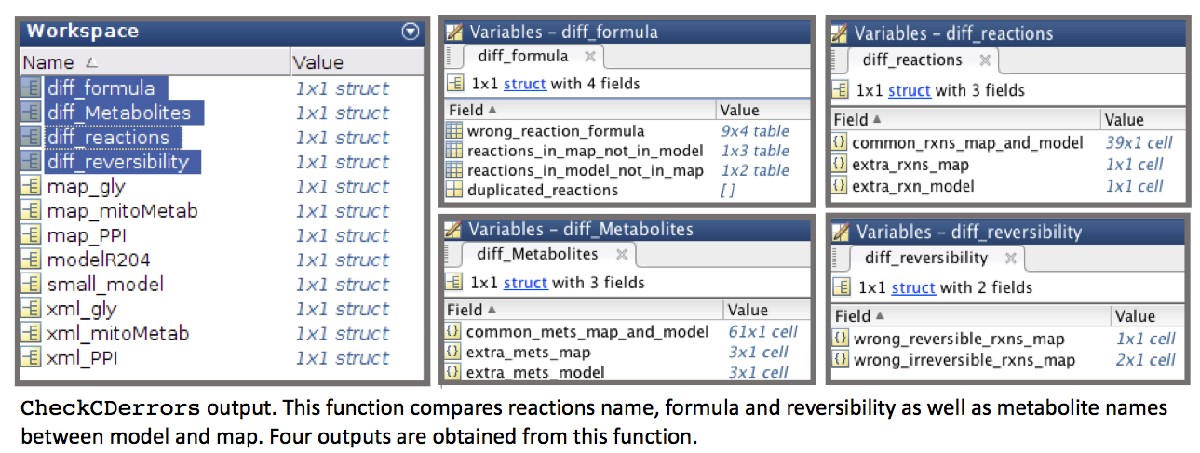

Four outputs are obtained from this function:

"`diffReactions`" summarises present and absent reactions between model and map.

"`diffMetabolites`" summarises present and absent metabolites. 

***NOTE!**** Note that having more metabolites and reactions in the COBRA model is normal since the model can contain more elements than the map. On the other hand, the map should only contain elements present in the model.*

 "`diffReversibility`" summarises discrepancies in defining the reversibility of reactions.

The last output "`diffFormula"` summarises discrepancies in reactions formulae (kinetic rates) and also lists duplicated reactions.

Some functions have been developed to modify attributes in the map automatically from MATLAB:  

- Errors in reaction names can be manually corrected in the Matlab structure with the function `correctRxnNameCD`. In the example one of the most common errors is shown: spaces in names are identified as errors.

correctRxns = diffReactions.extraRxnModel;
mapGlyCorrected = correctRxnNameCD(mapGly, ...
    diffReactions, correctRxns);

- Errors in metabolites can be corrected manually or automatically by the function `correctErrorMets` by giving a list of correct metabolite names. In the example, `"diffMetabolites.extraMetsModel"` correspond to the correct name of wrong metabolites in "`diffMetabolites.extraMetsMap"`.

correctMets = diffMetabolites.extraMetsModel;
mapGlyCorrected = correctMetNameCD(mapGlyCorrected, ...
    diffMetabolites, correctMets);

- Two functions can be used to solve errors in defining the reaction reversibility. The functions `transformToReversibleMap` and `transformToIrreversibleMap`, modify the reversibility of reactions in the map. Reaction lists obtained from "`diffReversibility"` can be used as an input of the next functions.

To correct a reversible reaction in the map, irreversible in the model. 

mapGlyCorrected = transformToIrreversibleMap(mapGlyCorrected, ...
    diffReversibility.wrongReversibleRxnsMap);

To correct a irreversible reaction in the map, reversible in the model. 

mapGlyCorrected = transformToReversibleMap(mapGlyCorrected, ...
    diffReversibility.wrongIrreversibleRxnsMap);

***NOTE!**** Reversibility errors due to base direction of the arrow can only be manually fixed in Cell designer. When creating a "reversible" reaction in CellDesigner, first a "irreverisble" reaction is created and has a particular direction. This "base" direction can be interpreted as an error as it dictates what metabolites are reactants or products.*

In order to check the reaction reversibility, reaction formulae can be printed from the map and model using different functions.

wrongFormula = mapFormula(mapGly, ...
    diffReversibility.wrongIrreversibleRxnsMap);

Print the same formula in the model to see the corrected formula: 

rightFormula = printRxnFormula(model, ...
    diffReversibility.wrongIrreversibleRxnsMap);

Print reaction formula from the corrected file mapGlyCorrected: 

correctedFormula = mapFormula(mapGlyCorrected, ...
    diffReversibility.wrongIrreversibleRxnsMap);

- **Anticipated results**

Before correcting formula's errors, run the control check again. Probably several errors in the output "`diffFormula`" have already been taken care of when correcting previous outputs.

[diffReactions, diffMetabolites, diffReversibility, diffFormula] = ...
    checkCDerrors(mapGlyCorrected,model);

***NOTE!**** Formula errors can only be manually corrected from the XML file in Cell designer.*

## 2. Export the modified MATLAB structure to CellDesigner XML file

In order to save the corrections previously made into an XML file, two functions are available depending on the MATLAB structure used.

## A) Parse a metabolic MATLAB structure

The "`transformMap2XML`" function parsed a MATLAB structure (from a simple metabolic map) into a XML file.  In order to save the previous corrections made.

transformMap2XML(xmlGly, ...
    mapGlyCorrected,'GlycolysisAndTCACorrected.xml');

## B) Parse a metabolic MATLAB structure combined with PPI

As in the parsing from XML to a MATLAB structure, a different function will be used when proteins and complexes are present in the map "`transformFullMap2XML`".

# Visualisation of Metabolic networks

## EQUIPMENT SETUP

CellDesigner uses the HTML-based colour format. This information if used to modify colors of pathways of interest such as Fluxes. The function `createColorsMap` contains all references for different colours HTML code to be directly recognised in Cell Designer and associated to a specific name. Therefore, users wont need to give a code but a colour name in capitals (143 colors are recognized).

% Check the list of available colours to use in Cell designer (retrieve 143 colors) 
% open createColorsMap.m

## 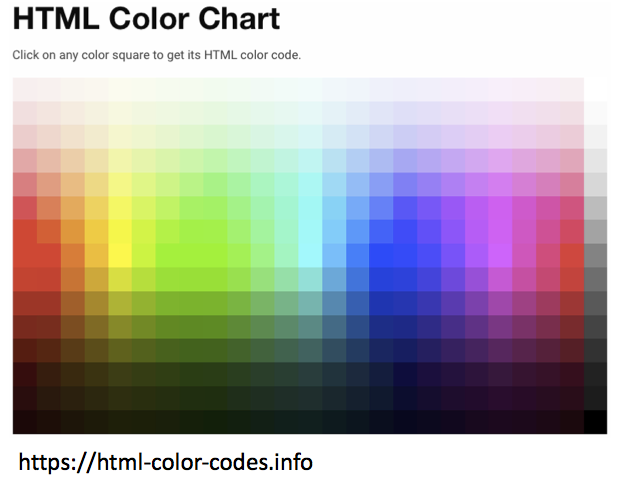

## PROCEDURE

Several modification can be done in the maps. All attributes can be easily reached in the COBRA type MATLAB structure and modified. The colour, name, type and size of nodes can be easily modified from MATLAB instead of doing it manually in CellDesigner. Furthermore, other attributes such as reaction type or reversibility (previously mentioned) can also be modified.

## **1. Change reaction colour and width**

The function `changeRxnColorAndWidth` modifies the width and colour of reactions provided in the form of a list of names.

- **Anticipated results**

All reactions present in the map can be coloured if the list given is extracted from the map and not from the model. See the next example: 

In the example, all reactions in the map will be coloured as Light-salmon and have a width of 10 (width=1 by default). Furthermore, the newly generated map will be transformed to be opened in CD.

mapGlyColoured = changeRxnColorAndWidth(mapGlyCorrected, ...
    mapGlyCorrected.rxnName, 'LIGHTSALMON',10);
transformMap2XML(xmlGly, mapGlyColoured,'mapGlyRxnColoured.xml');

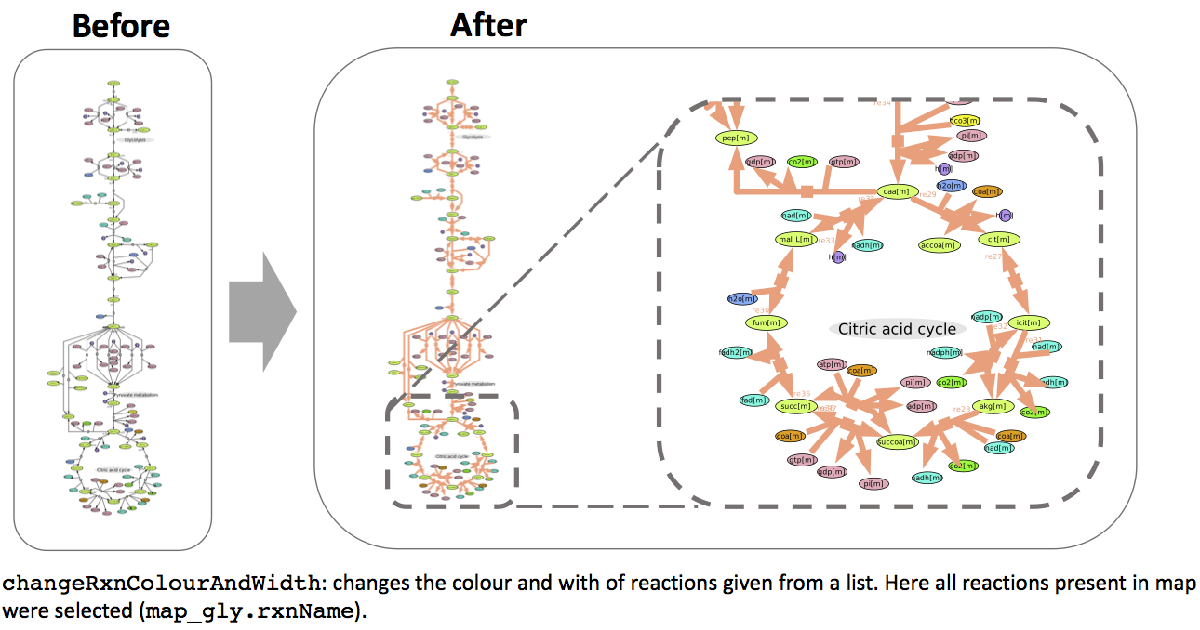

***NOTE! ****in this example all reactions present in the map are being given as input list. However, this list can contain a set of reactions given by the user.*

## 2. Add colour to metabolites

The function `addColourNode` adds colour to all nodes linked to a specific list of reactions. Taking as an example the previous list we can modify the colour of all those nodes in the map in Light-steel-blue. Furthermore, the newly generated map will be transformed into a XML file.

mapGlyColouredNodes = addColourNode(mapGlyColoured, ...
    mapGlyColoured.rxnName, 'LIGHTSTEELBLUE');
transformMap2XML(xmlGly, ...
    mapGlyColouredNodes,'mapGlyMetColoured.xml');

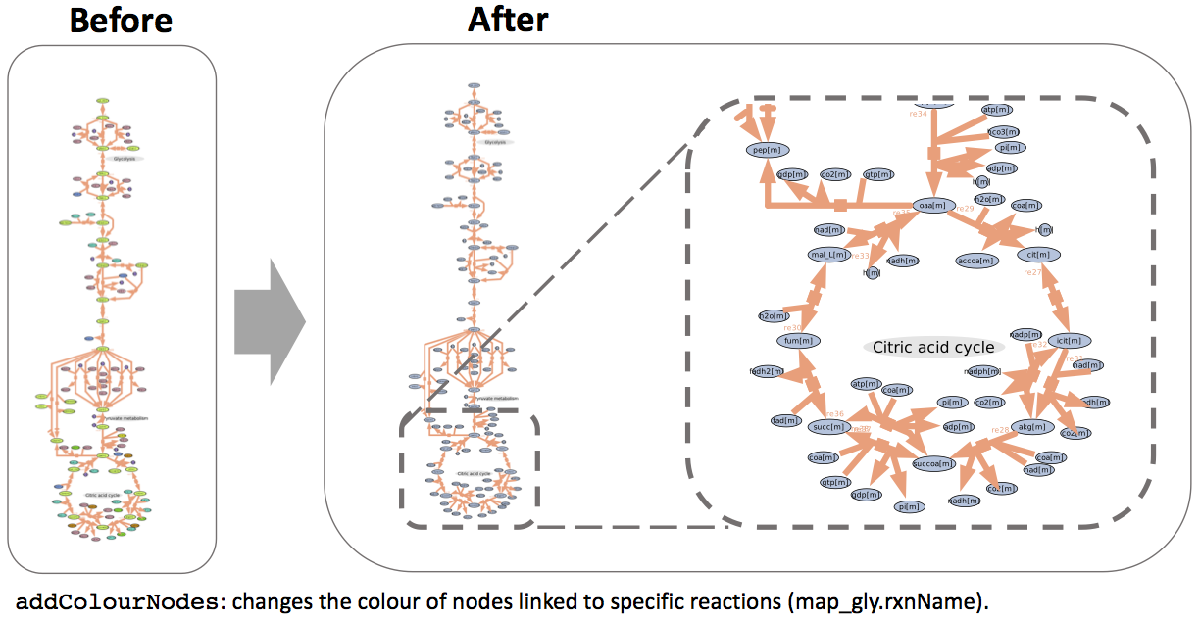

## **3. Changing the colour of individual metabolite**

It is possible to change the colour of specific metabolites in the map given a list of metabolite names. Here for example we want to visualise where ATP and ADP appear in order to give a global visual image of where energy is being produced and consumed.

First, for an easier visualisation all metabolites present in the map will be coloured in white. Afterwards, selected metabolites "mitochondrial ATP and ADP" will be coloured in Red. Finally, the newly generated map will be transformed into a XML file. 

mapATPADP = changeMetColor(mapGly, ...
    mapGly.specName, 'WHITE'); % Change the colour of all nodes in the map to white
mapATPADP = changeMetColor(mapATPADP, ...
    {'atp[m]'}, 'RED'); % Change specifically the colour of ATP and ADP
mapATPADP = changeMetColor(mapATPADP, {'adp[m]'}, 'RED');

transformMap2XML(xmlGly, mapATPADP, 'mapATPADPColoured.xml');

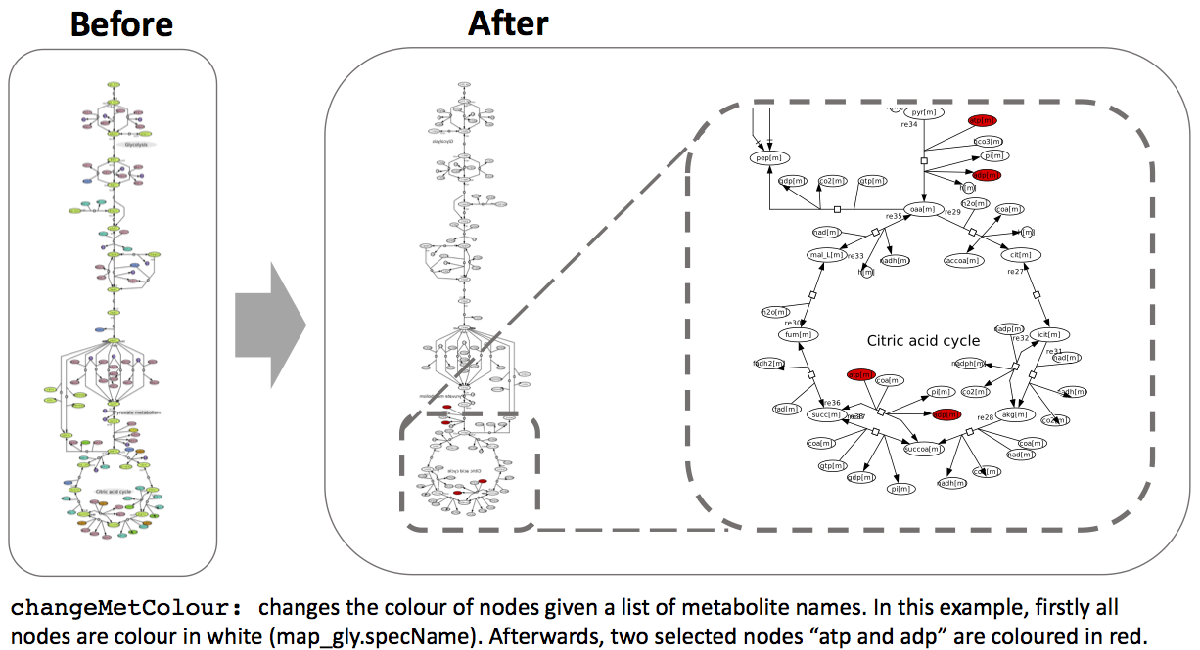

Furthermore, we can also color reactions linked to specific metabolites by combining functions for the COBRA models and Visualisation. The function `findRxnsFromMets `identify all reactions containing specific metabolites. Here we want to find reactions containing "mitochondrial ATP and ADP", and colour these reactions in "aquamarine".  Moreover,the newly generated map will be transformed into a XML file.

rxnsATPADP = findRxnsFromMets(model,{'atp[m]';'adp[m]'});
mapATPADPRxns = changeRxnColorAndWidth(mapATPADP, ...
    rxnsATPADP, 'AQUAMARINE' ,10);

transformMap2XML(xmlGly, mapATPADPRxns, 'mapATPADPRxnsColoured.xml');

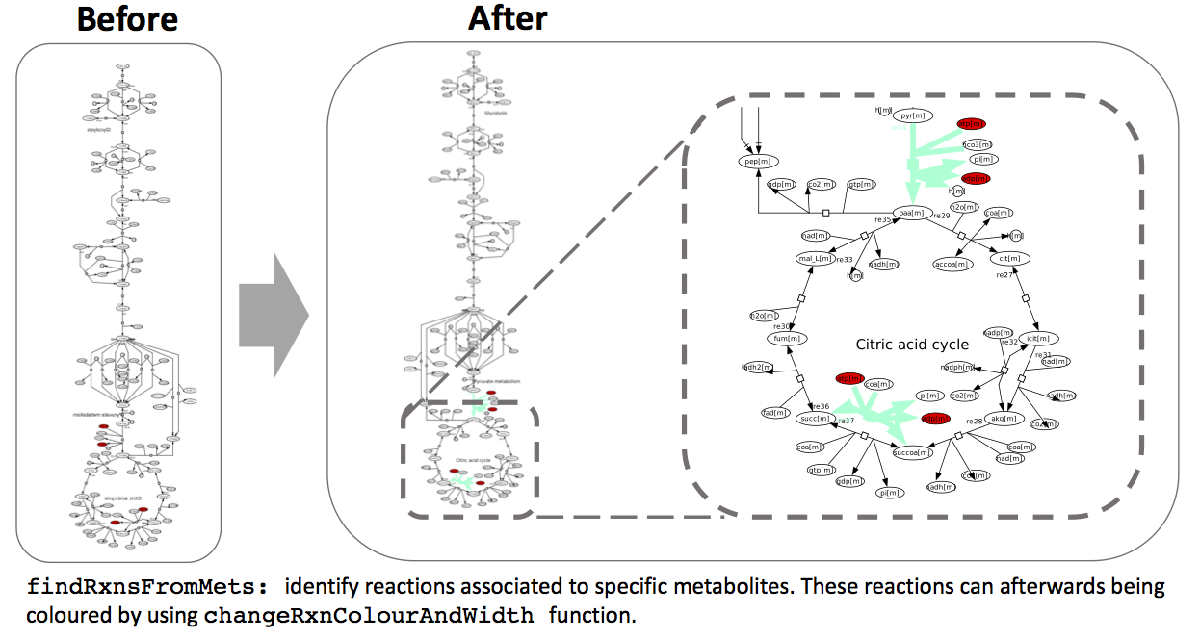

***NOTE! ****This funtion colors a list of specific metabolites whereas the function *`addColourNode `*color all nodes linked to a specific list of reactions.*

This combination of specific metabolites and reactions can be also directly done using the function `modifyReactionsMetabolites` mentioned before. However, using the functions described in this section, one can colour metabolites associated to the same reaction and chose colours in different ways. 

**(This tutorial continues in PART 2)***

**REFERENCES: **

- Hyduke D. COBRA Toolbox 2.0. *Nature Protocols *(2011). 

- Thiele, I., et al. "A community-driven global reconstruction of human metabolism". *Nat. Biotechnol.,* 31(5), 419-425 (2013).

- Funahashi A.  "CellDesigner: a process diagram editor for gene-regulatory and biochemical networks". *BIOSILICO*, 1:159-162, (2003).

- Kazuhiro A. "Integrating Pathways of Parkinson's Disease in a Molecular Interaction Map". *Mol Neurobiol*. 49(1):88-102 (2014).

- Calvo SE. "MitoCarta2.0: an updated inventory of mammalian mitochondrial proteins". *Nucleic Acids Res*. 4;44(D1):D1251-7 (2016).

- Shannon, Paul et al. “Cytoscape: A Software Environment for Integrated Models of Biomolecular Interaction Networks.” *Genome Research* 13.11 (2003): 2498–2504. *PMC*. Web. 5 Dec. (2017).

- Bonnet E. et al, "BiNoM 2.0, a Cytoscape plugin for accessing and analyzing pathways using standard systems biology formats". *BMC Syst Biol.* 1;7:18 (2013).